# Full simulation script all volume fractions all wavelengths

## Description

This script computes all scattering properties for IL dilutions under different volume fractions & wavelengths ranging from 400-1700 nm. this includes the scattering coefficient. anisotropy, reduced scattering coefficient & phase function under both the dependent and independent scattering regimes.

## References:

[1] Shahsavari, M., Kuiper, M., Engelaer, M., de Sivry-Houle, M. P., van Leeuwen, T. G., & van der Pol, E. (2026). Particle size distribution and concentration of Intralipid® 20%. *Journal of Biomedical Optics*, *31*(1), 015001-015001.

[2] Kedenburg, S., Vieweg, M., Gissibl, T., & Giessen, H. (2012). Linear refractive index and absorption measurements of nonlinear optical liquids in the visible and near-infrared spectral region. *Optical Materials Express*, *2*(11), 1588-1611.

[3] Li, X. C., Zhao, J. M., Liu, L. H., & Tan, J. Y. (2015). Optical properties of edible oils within spectral range from 300 to 2500 nm determined by double optical pathlength transmission method. *Applied Optics*, *54*(13), 3886-3893.

[4] Aernouts, B., Van Beers, R., Watté, R., Lammertyn, J., & Saeys, W. (2014). Dependent scattering in Intralipid® phantoms in the 600-1850 nm range. *Optics express*, *22*(5), 6086-6098.

[5] Schaefer, J., Lee, S. C., & Kienle, A. (2012). Calculation of the near fields for the scattering of electromagnetic waves by multiple infinite cylinders at perpendicular incidence. *Journal of Quantitative Spectroscopy and Radiative Transfer*, *113*(16), 2113-2123.

MatScat link: [https://nl.mathworks.com/matlabcentral/fileexchange/36831-matscat](https://nl.mathworks.com/matlabcentral/fileexchange/36831-matscat)

## Script start

close all
clear all
clc

## Loading in data & setting paths (change)

below various files to be loaded in and paths to be set to use functions or other necessary scripts

%laoding in Li (2015) data [3]
load('C:\Users\OCT Monster\Documents\Xavier\AIL\clean_code\soybean_li2015.mat')

%adding path for MatScat scripts [5]
addpath('C:\Users\OCT Monster\Documents\Xavier\AIL\clean_code')

## Refractive index curve

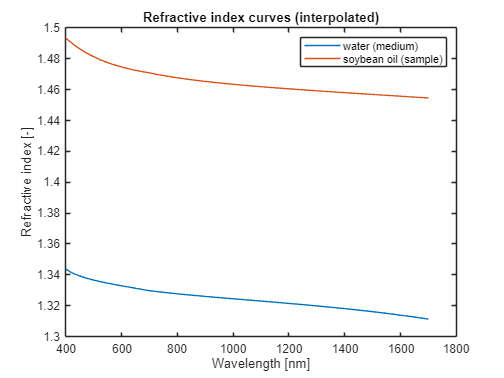

%pseudo-Sellmeier params [1]
params_soybean  = [2.12615032 6.84946354e-3   1.66137788e-2 2.35999596e-3];
params_H2O      = [1.78685001 -4.73643733e-2  1.85725893e-3 3.00086689e-1];

%wavelength vector [m]
lam_step        = 1; %[nm]
lam_vec         = (400:lam_step:1700)*1e-9;

%checking against refractiveindex.info source
nH20_ref        = n_fun_H20(lam_vec*1e6);

%two wavelength segments
lam1            = (400:lam_step:700)*1e-9;
lam2            = (700:lam_step:1700)*1e-9;
lam_tot         = (400:lam_step:1700)*1e-9;

%computing piecewise def of soybean oil
n_soy_MONA      = n_fun(params_soybean,lam1*1e6);
n_soy_MONA2     = n_fun(params_soybean,lam2*1e6);
n_soy_LI        = soy_ft(lam2*1e9)+7e-4;
n_H2O_MONA      = n_fun(params_H2O,lam1*1e6);
n_H2O_MONA2     = n_fun(params_H2O,lam2*1e6);
n_H2O_ref2      = n_fun_H20(lam2*1e6);

%computing difference @700nm
end_diff_H2O    = n_H2O_MONA(end) - n_H2O_ref2(1);
end_diff_soy    = n_soy_MONA(end) - n_soy_LI(1);

%concatenating vectors
n_H2O_tot       = [n_H2O_MONA n_H2O_ref2(2:end)+end_diff_H2O];
n_soy_tot       = [n_soy_MONA n_soy_LI(2:end)'+end_diff_soy];

%offset (for manual control)
% n_H2O_tot       = n_H2O_tot+0e-4;
% n_soy_tot       = n_soy_tot+0e-4;

%fits to compute index at arbitrary wavelength
ft_n_soy        = fit(lam_tot',n_soy_tot','smoothingspline');
ft_n_H20        = fit(lam_vec',n_H2O_tot','smoothingspline');

%plotting results
figure
plot(lam_vec*1e9,ft_n_H20(lam_vec))
hold on
plot(lam_tot*1e9,ft_n_soy(lam_vec))
xlabel('Wavelength [nm]')
ylabel('Refractive index [-]')
legend('water (medium)','soybean oil (sample)')
title('Refractive index curves (interpolated)')

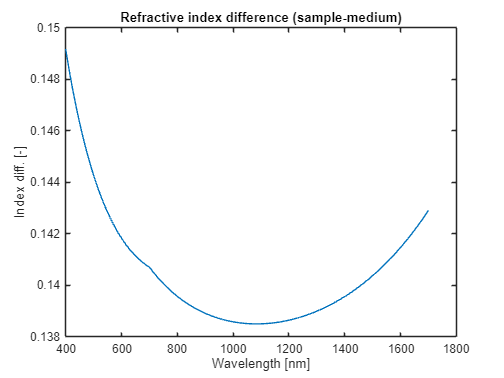


figure
plot(lam_vec*1e9,n_soy_tot-nH20_ref)
xlabel('Wavelength [nm]')
ylabel('Index diff. [-]')
title('Refractive index difference (sample-medium)')

## Defining particle sampling

%defining particle diameter vector
d_vec           = 58:2000;
%computing size distribution
[fd]            = size_dist(d_vec);
%defining fit to resample original distribution [1/mL/nm]
ft              = fit(d_vec',fd','smoothingspline');
%defining integrand
int_ft          =@(d) ft(d);
%bin edges
d_edges         = linspace(58,2000,140);
%bin centers (diameter & radius)
d_center        = (d_edges(2:end)+d_edges(1:end-1))/2;
%defining particle radius vector in [m]
r_center   = d_center'/2*1e-9;
%computing counts per bin
tmp_ct          = cumtrapz(d_edges,int_ft(d_edges));
N_bins          = diff(tmp_ct);
%normalizing
N_norm_MONA     = N_bins/sum(N_bins);

%setting total number of particles
N_tot_MONA      = 0.227/(sum(N_norm_MONA.*(4/3*pi*r_center.^3)));
%defining particle number densities
n_vec      = N_tot_MONA*N_norm_MONA;



## Dependent scattering

%test wavelengths
lam_test_vec    = [400:50:1700]*1e-9;
%phi_p values
phi_p_vec       = linspace(0.01,1,20)*0.227;

%number of Mie angles
N_ang           = 1000;

%init. results struct
res        = struct();

%starting parpool with N workers to avoid running out of memory. Important
%if the number of particle sizes and the number of angles is large.
%H-matrix dimensions are [NxNxNt] where N is number of particle sizes and
%Nt is number of angles! change based on the specifications of your
%computer. If the parallel processing toolbox is not available remove this
%sectio and convert the parfor below to a regular for loop.

taregt_workers  = 8;                % Desired number of workers
p               = gcp('nocreate');  % Get current pool, but do not create one
if isempty(p)
    % No active pool
    p = parpool('local', taregt_workers);
elseif p.NumWorkers ~= taregt_workers
    % Active pool exists, but with wrong number of workers
    delete(p);
    p = parpool('local', target_workers);
end

%looping over all wavelength values
for ilam = 1:length(lam_test_vec)

    %init. clock
    tic

    %selecting wavelength [m]
    lam_test    = lam_test_vec(ilam);
    %generating refractive index values @ test wavelength
    n_sample    = ft_n_soy(lam_test);
    n_medium    = ft_n_H20(lam_test);

    %wavenumber
    k01         = 2*pi*n_medium/lam_test;
    %p_vec
    p_vec1      = linspace(0,2*k01,N_ang);
    %linear angle
    p_tmp1      = 2*k01*sin(linspace(0,pi,N_ang)/2);
    %defining angular values in radians
    ang_rad1    = 2*asin(p_vec1/2/k01);

    Mie_sols = {};
    %pre-computing all Mie solutions
    for i = 1:length(r_center)
        %Mie solver MatScat (output: S-matrix, scattering cross-section, angles)
        [S, C, ANG] = calcmie(r_center(i),n_sample,n_medium,lam_test,N_ang);
        %re-sampling S-matrix to match p_vec
        S           = spline(p_tmp1,S,p_vec1);
        %storing solutions
        Mie_sols{i,1} = S;
        Mie_sols{i,2} = C;
    end

    %init all optical parameters
    mu_s_indep_save     = {};           %scattering coefficient under independent scattering [1/m]
    mu_s_dep_save       = {};           %scattering coefficient under dependent scattering [1/m]
    P_indep_save        = {};           %phase function under independent scattering [1/sr]
    P_dep_save          = {};           %phase function under dependent scattering [1/sr]
    g_indep_save        = {};           %anisotropy factor under independent scattering [-]
    g_dep_save          = {};           %anisotropy factor under dependent scattering [-]


    %parfor loop to increase speed
    parfor i = 1:length(phi_p_vec)

        %setting total number of particles
        N_tot_MONA      = phi_p_vec(i)/(sum(N_norm_MONA.*(4/3*pi*r_center.^3)));

        %defining particle number densities
        n_vec      = N_tot_MONA*N_norm_MONA;

        %computing dep. scattering
        [output] = PYHSA_simulator_publish(n_medium,r_center,n_vec,lam_test,N_ang,Mie_sols);

        %storing results
        mu_s_indep_save{i}    = output.mu_s_indep;
        mu_s_dep_save{i}      = output.mu_s_dep;
        P_indep_save{i}       = output.P_indep;
        P_dep_save{i}         = output.P_dep;
        g_indep_save{i}       = output.g_indep;
        g_dep_save{i}         = output.g_dep;


    end

    %computing mu_s_dep and g_dep according to Aernouts [4]
    [mu_s_ref,g_dep_ref] = fun_AERNOUTS(phi_p_vec,lam_test*1e9);

    %storing results in result struct()
    res(ilam).mu_s_indep    = [mu_s_indep_save{:}];
    res(ilam).mu_s_dep      = [mu_s_dep_save{:}];
    res(ilam).g_indep       = [g_indep_save{:}];
    res(ilam).g_dep         = [g_dep_save{:}];
    res(ilam).PF_indep      = [P_indep_save{:}];
    res(ilam).PF_dep        = [P_dep_save{:}];
    res(ilam).mu_s_ref      = mu_s_ref*100;                %Reference value scattering coefficient under DS (*100 to convert back to [1/m])
    res(ilam).g_ref         = g_dep_ref;                   %Reference value anisotropy under DS
    res(ilam).lambda        = lam_test;                    %wavelength under consideration
    res(ilam).angrad        = ang_rad1;                    %angle vector for phase function
    res(ilam).phi_p         = phi_p_vec;                   %volume fraction vector


    %timer
    t=toc;
    %loop update
    fprintf('Finished processing wavelength: %d nm (%d/%d). Elapsed time: %.4g seconds\n'...
        ,round(lam_test*1e9),ilam,length(lam_test_vec),t)


end

Finished processing wavelength: 400 nm (1/27). Elapsed time: 12.66 seconds
Finished processing wavelength: 450 nm (2/27). Elapsed time: 11.76 seconds
Finished processing wavelength: 500 nm (3/27). Elapsed time: 11.33 seconds
Finished processing wavelength: 550 nm (4/27). Elapsed time: 11.72 seconds
Finished processing wavelength: 600 nm (5/27). Elapsed time: 12.06 seconds
Finished processing wavelength: 650 nm (6/27). Elapsed time: 11.17 seconds
Finished processing wavelength: 700 nm (7/27). Elapsed time: 11.86 seconds
Finished processing wavelength: 750 nm (8/27). Elapsed time: 11.95 seconds
Finished processing wavelength: 800 nm (9/27). Elapsed time: 11.43 seconds
Finished processing wavelength: 850 nm (10/27). Elapsed time: 11.75 seconds
Finished processing wavelength: 900 nm (11/27). Elapsed time: 12.51 seconds
Finished processing wavelength: 950 nm (12/27). Elapsed time: 11.25 seconds
Finished processing wavelength: 1000 nm (13/27). Elapsed time: 11.25 seconds
Finished processing 

## Saving loop output

answer = questdlg( ...
    'Do you want to save the generated variable?', ...
    'Save variable?', ...
    'Yes', 'No', 'Yes');

if strcmp(answer, 'Yes')
    [fileName, folderName] = uiputfile( ...
        {'*.mat', 'MAT-files (*.mat)'}, ...
        'Save variable as');
    if isequal(fileName, 0) || isequal(folderName, 0)
        disp('Save cancelled by user.');
    else
        fullFileName = fullfile(folderName, fileName);
        save(fullFileName, 'res', '-v7.3');
        fprintf('Saved variable to:\n%s\n', fullFileName);
    end
else
    disp('Variable was not saved.');
end

Saved variable to:
C:\Users\OCT Monster\Documents\Xavier\AIL\clean_code\article scripts\test.mat


## example figures

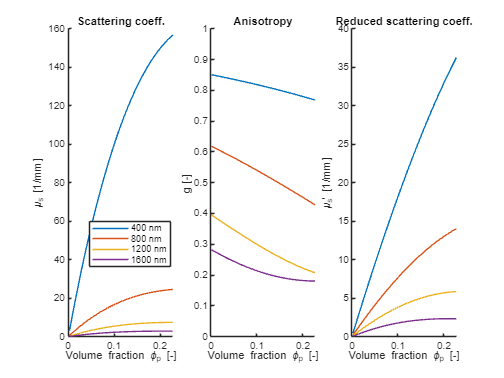

%selecting waveelngth indices
ilam_select = [1 9 17 25];

figure
%scattering coefficient
subplot(131)
hold on
for i = 1:length(ilam_select)
    plot(res(ilam_select(i)).phi_p,res(ilam_select(i)).mu_s_dep/1000)
end
xlabel('Volume fraction \phi_p [-]')
ylabel('\mu_s [1/mm]')
title('Scattering coeff.')

legend_labels = string(round(lam_test_vec(ilam_select)*1e9)) + " nm";
legend(legend_labels, 'Location', 'best')

%scattering anisotropy
subplot(132)
hold on
for i = 1:length(ilam_select)
    plot(res(ilam_select(i)).phi_p,res(ilam_select(i)).g_dep)
end
xlabel('Volume fraction \phi_p [-]')
ylabel('g [-]')
ylim([0 1])
title('Anisotropy')

%reduced scattering coeficient
subplot(133)
hold on
for i = 1:length(ilam_select)
    plot(res(ilam_select(i)).phi_p,res(ilam_select(i)).mu_s_dep/1000.*(1-res(ilam_select(i)).g_dep))
end
xlabel('Volume fraction \phi_p [-]')
ylabel('\mu_s'' [1/mm]')
title('Reduced scattering coeff.')


%selecting volume fraction indices (single wavlength)
iphi_select = [1 10 20];
ilam_select  = 9;

figure
for i = 1:length(iphi_select)
    semilogy(res(ilam_select).angrad,res(ilam_select).PF_dep(:,iphi_select(i)))
    hold on
    %proof of normalization
    trapz(res(ilam_select).angrad,2*pi*res(ilam_select).PF_dep(:,iphi_select(i)).*sin(res(ilam_select).angrad'))
end

ans =      1


ans =      9.999999999999998e-01


ans =      1


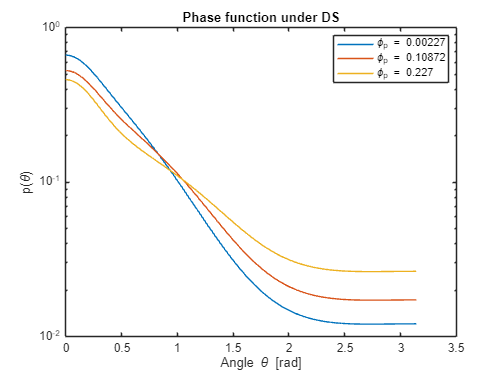

xlabel('Angle \theta [rad]')
ylabel('p(\theta)')
title('Phase function under DS')

legend_labels = "\phi_p = "+string(phi_p_vec(iphi_select));
legend(legend_labels, 'Location', 'best')

## Refractive index

function [n] = n_fun_H20(lam_um)

%Sellmeier curve extracted from:
%https://refractiveindex.info/?shelf=main&book=H2O&page=Kedenburg
%curve from 500-1750 nm

n = sqrt(1+0.75831.*lam_um.^2./(lam_um.^2-0.01007)+0.08495.*lam_um.^2./(lam_um.^2-8.961337));

end

function [n] = n_fun(params,lam_um)

%input: lam_um is the wavelength in microns (scalar or vector)
%input: params are the [A,B,C,D] parameters for the index curve
%output: n is the index curve (scalar or vector)

A = params(1);
B = params(2);
C = params(3);
D = params(4);

n = sqrt(A+B*lam_um.^2+C./(lam_um.^2-D^2));

end


## MONA size dist function

function [fd] = size_dist(d_vec)

%input d_vec is particle diameter in [nm].
%output fd is size distribution [AU]

%size distribution parameters
A = 151.5;
B = -231.2;
C = 109.9;
D = -22.18;
E = 12.53;
F = -2.417;
G = 9.609;

%defining normalized diameter
d_norm  = d_vec/1000;
%init. relative fraction vector
fd      = zeros(size(d_vec));

%looping through all d_vec values
for i = 1:length(d_vec)

    %splitting up cased by size
    if d_vec(i)>57 && d_vec(i)<700
        fd(i) = 10^(polyval([A B C D E],d_norm(i)));
    elseif d_vec(i)>=700 && d_vec(i)<2500
        fd(i) = 10^(polyval([F G],d_norm(i)));
    else
        fd(i) = 0;
    end

end

end


## Aernouts computation

function [mu_s,g_dep] = fun_AERNOUTS(phi_p,lam)

% input:
% phi_p:    (scalar) volume fraction concentration of IL (0-0.227)
% lam:      (vector) wavelength [nm]
% output:
% mu_s:     computed scattering coefficient vector [1/cm]

% derived from [4]

%independent scattering (full concentration)
mu_s_indep  = 1.868e10.*lam.^(-2.59);
%packing parameter
p_param     = 1.31 + 0.0005481.*lam;
%dependent scattering
mu_s        = mu_s_indep/0.227*phi_p.*((1-phi_p).^(p_param+1))./((1+phi_p.*(p_param-1)).^(p_param-1));

%parameters for computing anisotropy
g_a = 1.094;
g_b = -5.653e-4;
g_c = 5.3e-3;
g_f = 0.3516;
g_h = 0.1933;
g_d = g_a*(g_f-1)/(g_b*(g_h-1));

%anisotropy coeffcient for indep. scattering regime
g_indep =@(lam) g_a*((1-g_f)./(1+exp(g_c*(lam+g_d)))+g_f)+g_b*((1-g_h)./(1+exp(g_c*(lam+g_d)))+g_h).*lam;

%k_lambda function
k_fun =@(lam) -10+0.05047.*lam-9.693e-5.*lam.^2+8.449e-8.*lam.^3-3.412e-11.*lam.^4+5.204e-15.*lam.^5;

%anisotropy in dependent scattering
g_dep = g_indep(lam)+k_fun(lam).*phi_p;


end